## Úloha 1: Odhad zpoždění signálu pomocí LMS filtru

Použijte data v souboru `delayedvoice.mat`.

1) Najděte kauzální nebo nekauzální filtr, který filtrováním signálu **x** dává signál co nejvíce podobný signálu **d**. Filtr spočítejte řešením soustavy lineárních rovnic a potom pomocí Levinson-Durbinova algoritmu (funkce `miso_firwiener.m)`. Filtr počítejte z celých dat.

2) Simulujte jiný typ pozorování **x**, který vznikne degradací signálu **d**. Příklad: přičtení bílého šumu, přičtení úzkopásmového šumu/harmonického signálu.

3) Vyhodnoťte poměr signál/šum (SNR) před a po zpracování signálu **x** filtrem.

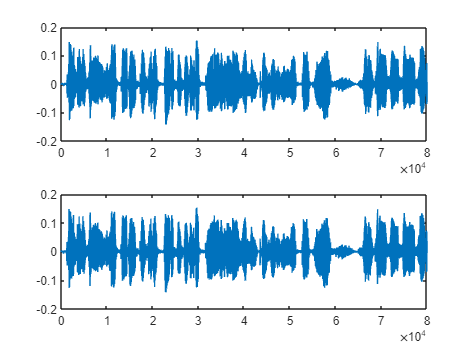

clc; clear all; close all;

load("delayedvoice.mat")

subplot(2,1,1)
plot(x)
subplot(2,1,2)
plot(d)

figure()

signaly se lisi o filtr, ktery lze spocitat pomoci LMS

**w_**LMS = **R^***-*1**p**  

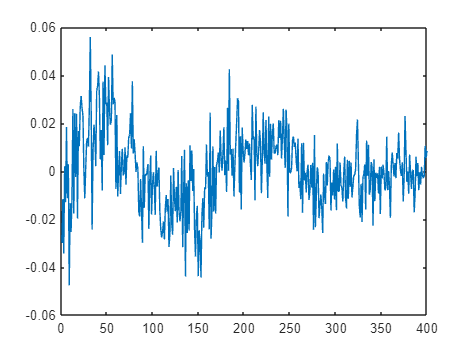

L = 400;
X = toeplitz(x(1)*eye(L, 1), x);
p = X*d';
R = X*X';%/length(x);
w = R\p;
plot(w)

Tady hledame filtr ktery by byl jenom zpozdenim - co kdyz ale dorazil driv signal na druhej snimac?

Zajistime nekauzalitu - posunem signalu d treba o 100.

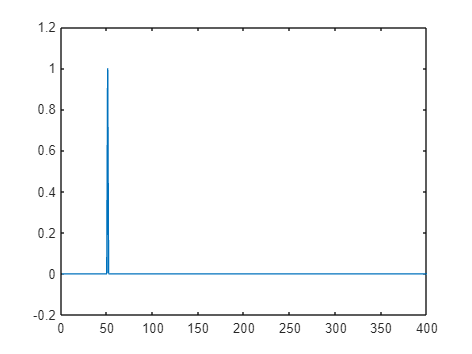

delay = 100;
d_delayed = [zeros(1, delay) d(1:end-delay)];
p_del = X*d_delayed';
w_del = R\p_del;
plot(w_del)

Delay je dobrej pri 50 - da peak do nuly. Kdyz dam 49, tak to filtr deformuje.

Now for misofirwiener. d taky musi byt delayed.

MISO = multiple input single output

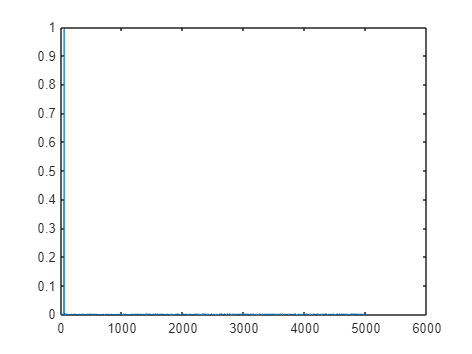

L = 5000;
w = miso_firwiener(L, x', d_delayed');
plot(w)

### Degradace signalu d

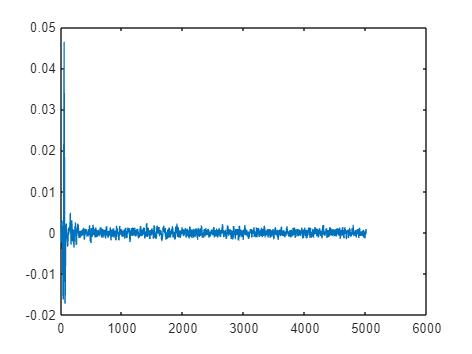

x_degraded = x + 0.1*randn(size(x));
w = miso_firwiener(L, x_degraded', d_delayed');
plot(w)

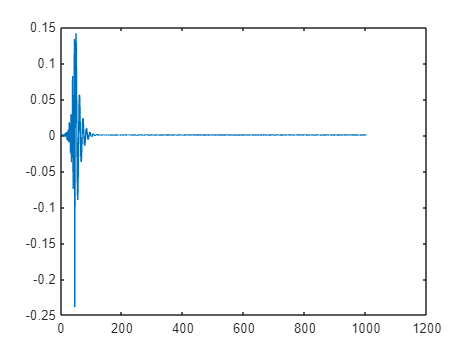


L = 1000;
x_degraded = filter(randn(1, 10), 1, x);
w = miso_firwiener(L, x_degraded', d_delayed');
plot(w)

### SNR

L = 1000;
noise = randn(size(x))*0.5;
xx = x + noise;
SNRin = var(x)/var(noise);
10*log10(SNRin)

ans = -24.9222

filter(w, 1, xx) = filter(w, 1, x) + filter(w, 1, noise) = filter(w, 1, x + noise)

w = miso_firwiener(L, xx', d_delayed');
y = filter(w, 1, xx);
y_noise = filter(w, 1, noise);
SNRout = var(filter(w, 1, x))/var(y_noise);
10*log10(SNRout)

ans = -12.3571